# Projeto - Eletromagnetismo e Ondulatória

## Modelando Antena Emissora

ant = spiralArchimedean('Turns', 6) % entre 3 e 6 voltas

ant =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 6
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


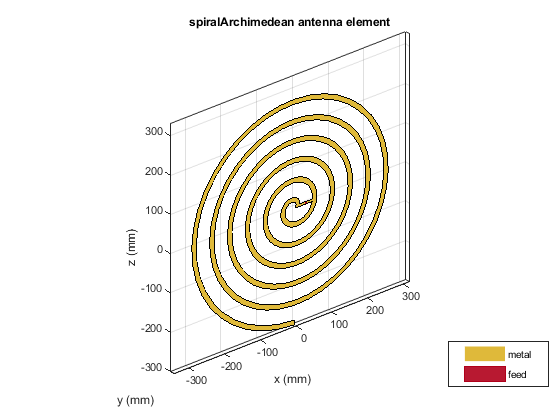

ant.NumArms = 1; % número de braços (ramos)  = 1
ant.Tilt = 90; % Inclinação da antena plano 3D
ant.OuterRadius = 30e-2; 
ant.InnerRadius = 10e-6;
show(ant)

## Impedância da Antena

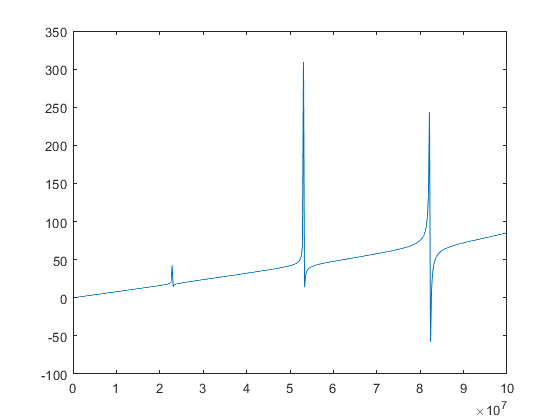

f = linspace(1e6, 1e8, 400);

impedancia = impedance(ant,f);
imaginario = imag(impedancia);
plot(f,imaginario)

## Modelando Antena Receptora